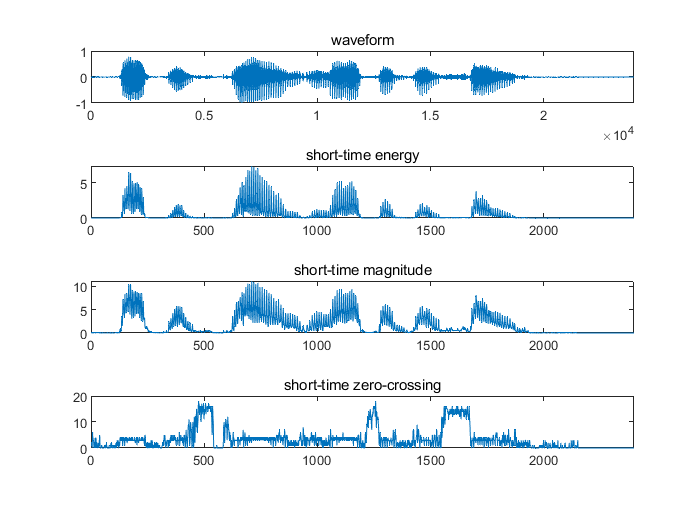

[signal, Fs] = audioread('s5.wav');
R = 10; % window_shift;
L = [51, 101, 201, 401]; %window_size;
figure;
analyze('s5.wav','R',R,21)

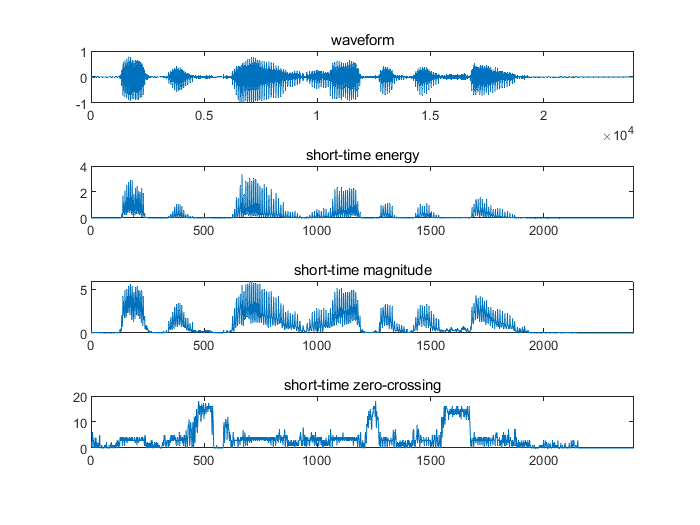

figure
analyze('s5.wav','H',R,21)

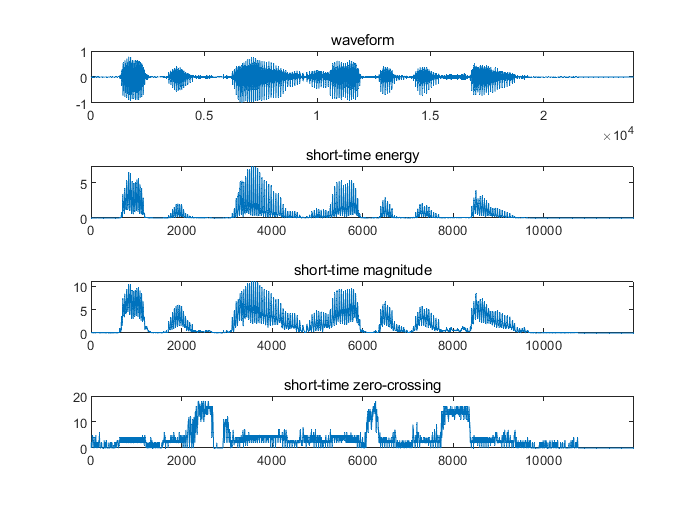

figure
analyze('s5.wav','R',2,21)

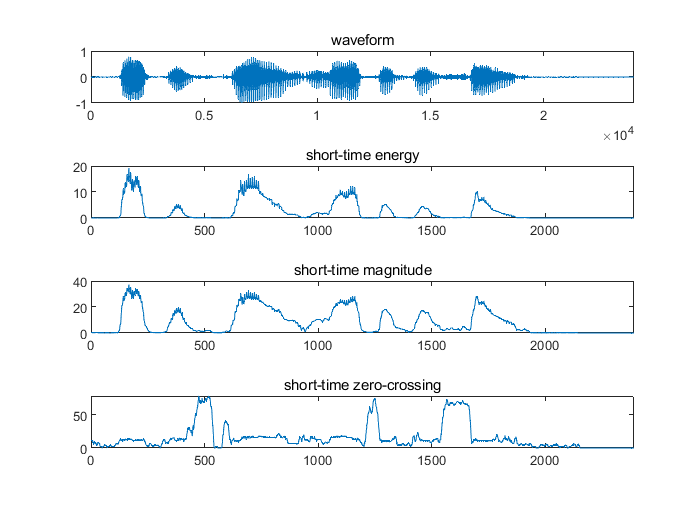

figure;
analyze('s5.wav','R',R,101)

% short-time energy
% figure()
% for j = 1:4
%     stenergy = zeros(1, round((length(signal)-L(j))/R));
%     window = hamming(L(j));
%     window_e = window.^2;
%     for i = 1:length(stenergy)
%         map_i = (i-1)*R+1;
%         stenergy(i) = sum((signal(map_i:(map_i+L(j)-1)).^2).*window_e);
%     end
%     subplot(4,1,j);plot(stenergy);title(sprintf('short-time energy when L=%d', L(j)));xlim([0,length(stenergy)]);
% end
% 
% % short time magnitude
% figure()
% for j = 1:4
%     stmagnitude = zeros(1, round((length(signal)-L(j))/R));
%     window = hamming(L(j));
%     for i = 1:length(stmagnitude)
%         map_i = (i-1)*R+1;
%         stmagnitude(i) = sum(abs(signal(map_i:map_i+L(j)-1)).*window);
%     end
%     subplot(4,1,j);plot(stmagnitude);title(sprintf('short-time magnitude when L=%d',L(j)));xlim([0,length(stmagnitude)]);
% end
% 
% % short time zero crossing
% for j = 1:4
%     stzeroc = zeros(1, round((length(signal)-L(j))/R));
%     Hzerocross = dsp.ZeroCrossingDetector;
%     for i = 1:length(stzeroc)
%         map_i = (i-1)*R+1;
%         stzeroc(i) = step(Hzerocross,signal(map_i:map_i+L(j)-1));
%     end
%     subplot(4,1,j);plot(stzeroc);title(sprintf('short-time zero-crossing when L=%d',L(j)));xlim([0,length(stzeroc)]);
%     
% end


function [  ] = analyze( input_file, window_type, window_shift, window_size)

signal = audioread(input_file);
R = window_shift;
L = window_size;
figure;
subplot(4,1,1);plot(signal);title('waveform');xlim([0,length(signal)]);

if window_type == 'R'
    window = ones(1,L)';
elseif window_type == 'H'
    window = hamming(L);
end

% short time energy
window_e = window.^2;
stenergy = zeros(1, round((length(signal)-L)/R));
for i = 1:length(stenergy)
    map_i = (i-1)*R+1;% map_i is n hat, beginning of each small piece 
    stenergy(i) = sum((signal(map_i:map_i+L-1).^2).*window_e);
end
subplot(4,1,2);plot(stenergy);title('short-time energy');xlim([0,length(stenergy)]);

% short time magnitude, almost the same with stenergy
stmagnitude = zeros(1, round((length(signal)-L)/R));
for i = 1:length(stmagnitude)
    map_i = (i-1)*R+1;
    stmagnitude(i) = sum(abs(signal(map_i:map_i+L-1)).*window);
end
subplot(4,1,3);plot(stmagnitude);title('short-time magnitude');xlim([0,length(stmagnitude)]);

% short time zero-crossing rate, using the object to calculate
stzeroc = zeros(1, round((length(signal)-L)/R));
Hzerocross = dsp.ZeroCrossingDetector;
for i = 1:length(stzeroc)
    map_i = (i-1)*R+1;
    stzeroc(i) = step(Hzerocross,signal(map_i:map_i+L-1));
end
subplot(4,1,4);plot(stzeroc);title('short-time zero-crossing');xlim([0,length(stzeroc)]);

end

